piv = load("PIVdata.txt");

uvel = piv(:,3);
vvel = piv(:,4);
xcoor = piv(1:100,1);
ycoor = flipud(piv(1:100:10000,2));

reshapeu = reshape(uvel,[10000 400]);
reshapev = reshape(vvel,[10000 400]);

meanusub = zeros(10000,400);
for i = 1:10000
    for j = 1:400
        meanusub(i,j) = reshapeu(i,j) - mean(reshapeu(i,:));
    end
end

meanvsub = zeros(10000,400);
for i = 1:10000
    for j = 1:400
        meanvsub(i,j) = reshapev(i,j) - mean(reshapev(i,:));
    end
end

meanuval = zeros(10000,1);
for i = 1:10000
        meanuval(i,1) = mean(reshapeu(i,:));
end

meanvval = zeros(10000,1);
for i = 1:10000
        meanvval(i,1) = mean(reshapev(i,:));
end

reumean = transpose(reshape(meanuval,[100 100]));
revmean = transpose(reshape(meanvval,[100 100]));

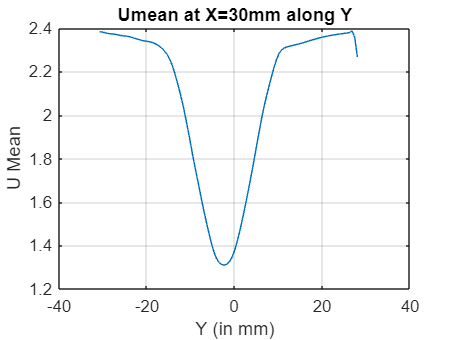

plot(ycoor,reumean(:,40))
grid on
title("Umean at X=30mm along Y");
xlabel("Y (in mm)");
ylabel("U Mean");

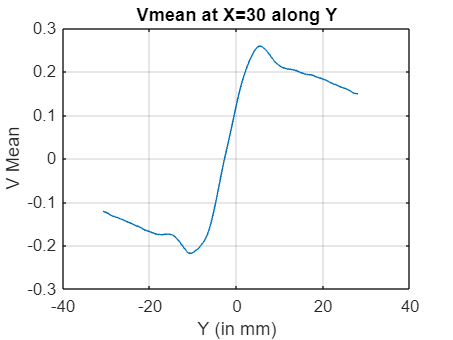

plot(ycoor,revmean(:,40))
grid on
title("Vmean at X=30 along Y")
xlabel("Y (in mm)");
ylabel("V Mean");

rmsu = zeros(10000,1);
for i = 1:10000
    rmsu(i,1) = rms(meanusub(i,:));
end

rmsv = zeros(10000,1);
for i = 1:10000
    rmsv(i,1) = rms(meanvsub(i,:));
end

reurms = transpose(reshape(rmsu,[100 100]));
revrms = transpose(reshape(rmsv,[100 100]));

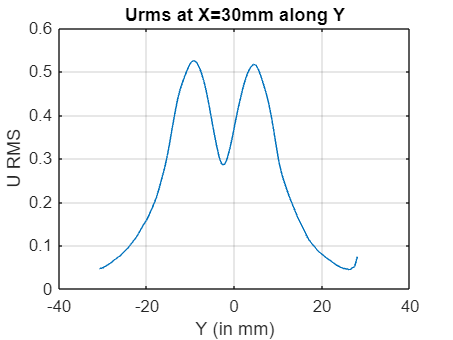

plot(ycoor,reurms(:,40))
grid on
title("Urms at X=30mm along Y");
xlabel("Y (in mm)");
ylabel("U RMS");

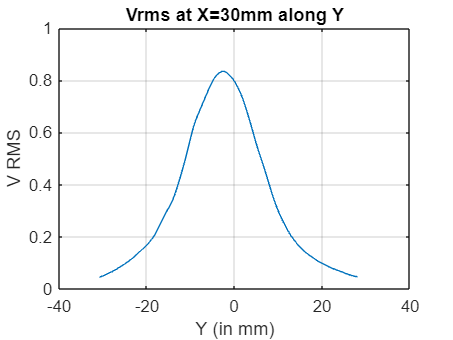

plot(ycoor,revrms(:,40))
grid on
title("Vrms at X=30mm along Y");
xlabel("Y (in mm)");
ylabel("V RMS");

flumul = zeros(10000,400);
for i = 1:10000
    for j = 1:400
        flumul(i,j) = meanusub(4740,j)*meanusub(i,j);
    end
end

mulavg = zeros(10000,1);
for i = 1:10000
    mulavg(i,1) = (mean(flumul(i,:))*400)/(rms(meanusub(4740,:))^2);
end

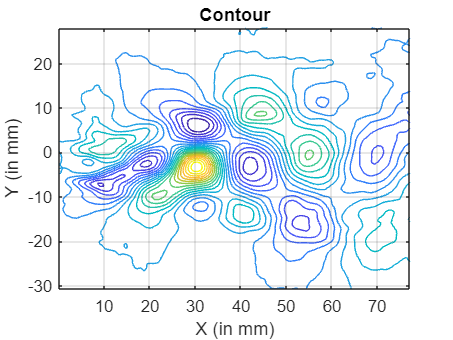

contour(xcoor,ycoor,transpose(reshape(mulavg,[100 100])),20)
grid on
title("Contour");
xlabel("X (in mm)");
ylabel("Y (in mm)");

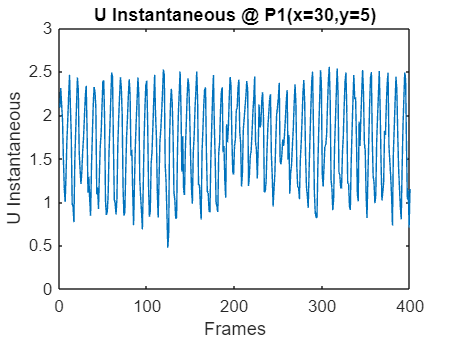

plot(reshapeu(3840,:))
title("U Instantaneous @ P1(x=30,y=5)");
xlabel("Frames");
ylabel("U Instantaneous");

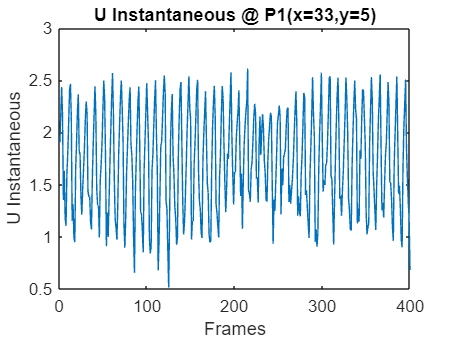

plot(reshapeu(3844,:))
title("U Instantaneous @ P1(x=33,y=5)");
xlabel("Frames");
ylabel("U Instantaneous");

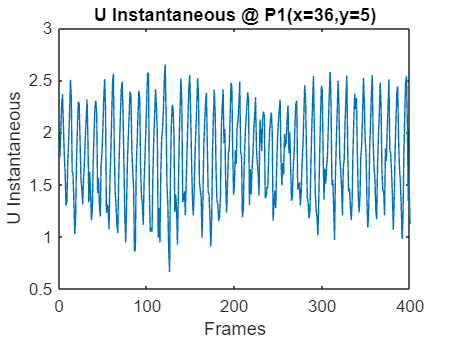

plot(reshapeu(3848,:))
title("U Instantaneous @ P1(x=36,y=5)");
xlabel("Frames");
ylabel("U Instantaneous");

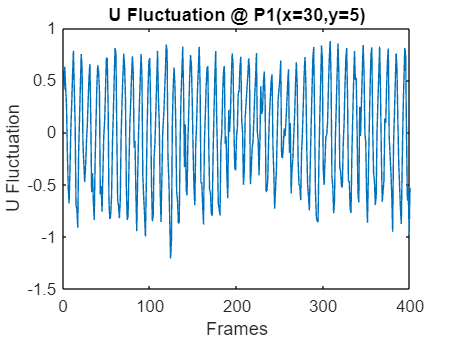

plot(meanusub(3840,:))
title("U Fluctuation @ P1(x=30,y=5)");
xlabel("Frames");
ylabel("U Fluctuation");

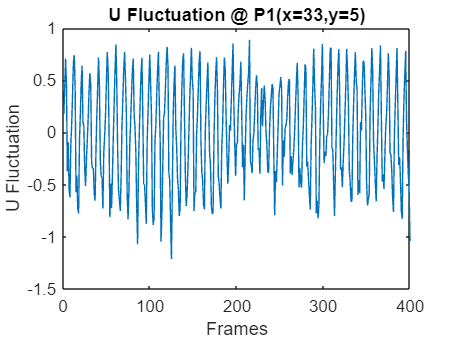

plot(meanusub(3844,:))
title("U Fluctuation @ P1(x=33,y=5)");
xlabel("Frames");
ylabel("U Fluctuation");

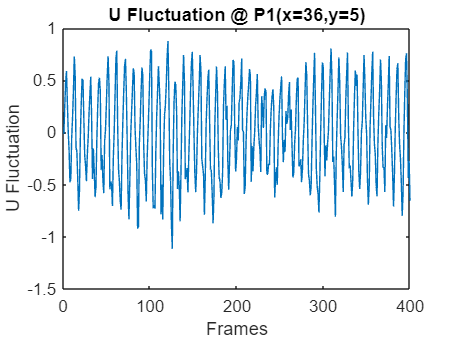

plot(meanusub(3848,:))
title("U Fluctuation @ P1(x=36,y=5)");
xlabel("Frames");
ylabel("U Fluctuation");

p1 = meanusub(3840,:);
p2 = meanusub(3844,:);
p3 = meanusub(3848,:);

n = length(p1);

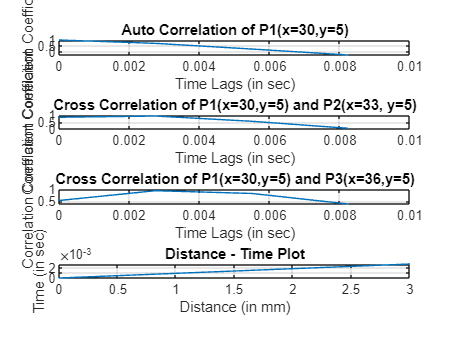

corrcoff1 = zeros(1,n);
corrcoff2 = zeros(1,n);
corrcoff3 = zeros(1,n);
mul = 0;
p1flu = p1 - mean(p1);
p2flu = p2 - mean(p2);
p3flu = p3 - mean(p3);
rmsq1 = (rms(p1flu))^2;
rmsq2 = (rms(p1flu)*rms(p2flu));
rmsq3 = (rms(p1flu)*rms(p3flu));

for dt = 0:n-1
    mul1 = 0;
    mul2 = 0;
    mul3 = 0;
    for t = 1:n-dt
        mul1 = mul1 + (p1flu(1,t)*p1flu(1,(t+dt)));
        mul2 = mul2 + (p1flu(1,t)*p2flu(1,(t+dt)));
        mul3 = mul3 + (p1flu(1,t)*p3flu(1,(t+dt)));
    end
    corrcoff1(dt+1) = (mul1/n)/rmsq1;
    corrcoff2(dt+1) = (mul2/n)/rmsq2;
    corrcoff3(dt+1) = (mul3/n)/rmsq3;
end
subplot(4,1,1)
x = 0:3;
plot(x./364,corrcoff1(1,1:4))
grid on
title("Auto Correlation of P1(x=30,y=5)");
xlabel("Time Lags (in sec)");
ylabel("Correlation Coefficient");
subplot(4,1,2)
x = 0:3;
plot(x./364,corrcoff2(1,1:4))
grid on
title("Cross Correlation of P1(x=30,y=5) and P2(x=33, y=5)");
xlabel("Time Lags (in sec)");
ylabel("Correlation Coefficient");
subplot(4,1,3)
x = 0:3;
plot(x./364,corrcoff3(1,1:4))
grid on
title("Cross Correlation of P1(x=30,y=5) and P3(x=36,y=5)");
xlabel("Time Lags (in sec)");
ylabel("Correlation Coefficient");

deltat1 = (find(corrcoff1 == max(corrcoff1))-1)/364;
deltat2 = (find(corrcoff2 == max(corrcoff2))-1)/364;
deltat3 = (find(corrcoff3 == max(corrcoff3))-1)/364;
subplot(4,1,4)
a = plot([0 3], [deltat1 deltat2]);
grid on
title("Distance - Time Plot");
xlabel("Distance (in mm)");
ylabel("Time (in sec)");

convvel = mean(gradient([0 3], [deltat1 deltat2]))

convvel = 1092